use_marginalized_solver = true;
verbose = true;
fpath = "/home/alan/experimental_data/tiers/ros2/factor_graph.pyfg"

fpath = "/home/alan/experimental_data/tiers/ros2/factor_graph.pyfg"

prob = parse_pyfg_text(fpath, use_marginalized_solver, verbose);

Using marginalized product.
Reading data from /home/alan/experimental_data/tiers/ros2/factor_graph.pyfg
Finished loading data in 0.773321 seconds.


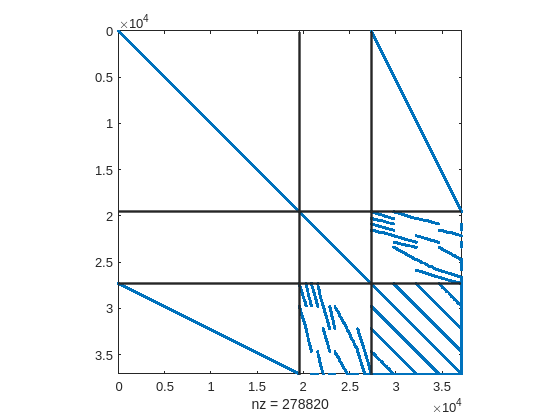

n = size(prob.Qmain, 1);
npose = prob.num_poses;
d = prob.dim;
l = prob.num_range_measurements;
t = prob.num_landmarks+prob.num_poses;
trans_idxs = prob.all_t_idxs;
range_idxs = prob.all_d_idxs;
rot_idxs = prob.all_R_idxs;

figure(1)
spy(prob.Q);
hold on;
trans_line = min(trans_idxs);
range_line = min(range_idxs);
xline(trans_line, LineWidth=2);
yline(trans_line, LineWidth=2);
xline(range_line, LineWidth=2);
yline(range_line, LineWidth=2);

## Loop closures between robot and all landmarks

Robots: 2 || Variables: 102 poses, 3 landmarks || Measurements: 100 odom, 100 pose to landmark, 350 range, 98 loop closures, Interrobot loop closures: ('A', 'B'): 47 loop closures

fpath = "/home/alan/data_matrix_all_loop_closures.pyfg";
prob = parse_pyfg_text(fpath, use_marginalized_solver, verbose);

Using marginalized product.
Reading data from /home/alan/data_matrix_all_loop_closures.pyfg


Finished loading data in 0.120304 seconds.


n = size(prob.Qmain, 1);
npose = prob.num_poses;
d = prob.dim;
l = prob.num_range_measurements;
t = prob.num_landmarks+prob.num_poses;
trans_idxs = prob.all_t_idxs;
range_idxs = prob.all_d_idxs;
rot_idxs = prob.all_R_idxs;
X_gt = prob.X_gt;

X_gt_marg = X_gt(1:n, :);
X_gt_rot = X_gt(rot_idxs, :);
X_gt_range = X_gt(range_idxs, :);
X_gt_trans = X_gt(size(prob.Qmain, 1)+1:end, :);

Omega_t = prob.debug.Omega_t;
Omega_r = prob.debug.Omega_r;
A_t = prob.debug.A_t;
A_r = prob.debug.A_r;
T = prob.debug.T;
D = prob.debug.D;
Lrho = prob.debug.LGrho;

M = blkdiag(T, D);
Omega = blkdiag(Omega_t, Omega_r);
sqrtOmega = sqrt(Omega);
A = [A_t; A_r];

Qother_left = M' * sqrtOmega;
kernel = (pinv(full(A(:, 1:end-1)' * sqrtOmega)) * (A(:, 1:end-1)' * sqrtOmega));
Qother_middle = speye(size(Omega)) - kernel;
Qother_right = Qother_left';
Qother = Qother_left * Qother_middle * Qother_right;
Qtemp =  Qother_middle * Qother_right;

AsqrtOmega = A' * sqrtOmega;

Qhand = blkdiag(Lrho, zeros(size(Qother, 1) - size(Lrho, 1)));
Qhand = Qhand + Qother;

base_dim = size(Qhand, 1)

base_dim = 554


% check ranks of all of the different things
kernel_rank = rank(kernel)

kernel_rank = 104

kernel_rank_gap = base_dim - rank(kernel)

kernel_rank_gap = 450


Qother_mid_rank = rank(Qother_middle)

Qother_mid_rank = 544

Qother_mid_rank_gap = base_dim - rank(Qother_middle)

Qother_mid_rank_gap = 10

Qother_right_rank = rank(full(Qother_right))

Qother_right_rank = 552

Qother_right_rank_gap = base_dim - rank(full(Qother_right))

Qother_right_rank_gap = 2

Qother_rank_gap = size(Qother, 1) - rank(full(Qother))

Qother_rank_gap = 10



% tij = M * X_gt_marg;
% tij - (A * -X_gt_trans)
newest_null_after_X_gt = null(Qhand + X_gt(1:n, :) * X_gt(1:n, :)');
fprintf("Dimensionality of newest null space after removing X_gt: %d\n", size(newest_null_after_X_gt, 2));

Dimensionality of newest null space after removing X_gt: 0


## Loop closures only on robots

Robots: 2 || Variables: 102 poses, 3 landmarks || Measurements: 100 odom, 0 pose to landmark, 350 range, 98 loop closures, Interrobot loop closures: ('A', 'B'): 48 loop closures

fpath = "/home/alan/data_matrix_only_pose_loop_closures.pyfg";
prob = parse_pyfg_text(fpath, use_marginalized_solver, verbose);
n = size(prob.Qmain, 1);
npose = prob.num_poses;
d = prob.dim;
l = prob.num_range_measurements;
t = prob.num_landmarks+prob.num_poses;
trans_idxs = prob.all_t_idxs;
range_idxs = prob.all_d_idxs;
rot_idxs = prob.all_R_idxs;
X_gt = prob.X_gt;

X_gt_marg = X_gt(1:n, :);
X_gt_rot = X_gt(rot_idxs, :);
X_gt_range = X_gt(range_idxs, :);
X_gt_trans = X_gt(size(prob.Qmain, 1)+1:end, :);

Omega_t = prob.debug.Omega_t;
Omega_r = prob.debug.Omega_r;
A_t = prob.debug.A_t;
A_r = prob.debug.A_r;
T = prob.debug.T;
D = prob.debug.D;
Lrho = prob.debug.LGrho;

M = blkdiag(T, D);
Omega = blkdiag(Omega_t, Omega_r);
sqrtOmega = sqrt(Omega);
A = [A_t; A_r];

Qother_left = M' * sqrtOmega;
kernel = (pinv(full(A(:, 1:end-1)' * sqrtOmega)) * (A(:, 1:end-1)' * sqrtOmega));
Qother_middle = speye(size(Omega)) - kernel;
Qother_right = Qother_left';
Qother = Qother_left * Qother_middle * Qother_right;
Qtemp =  Qother_middle * Qother_right;

AsqrtOmega = A' * sqrtOmega;

Qhand = blkdiag(Lrho, zeros(size(Qother, 1) - size(Lrho, 1)));
Qhand = Qhand + Qother;

base_dim = size(Qhand, 1)

% check ranks of all of the different things
kernel_rank = rank(kernel)
kernel_rank_gap = base_dim - rank(kernel)

Qother_mid_rank = rank(Qother_middle)
Qother_mid_rank_gap = base_dim - rank(Qother_middle)
Qother_right_rank = rank(full(Qother_right))
Qother_right_rank_gap = base_dim - rank(full(Qother_right))
Qother_rank_gap = size(Qother, 1) - rank(full(Qother))


% tij = M * X_gt_marg;
% tij - (A * -X_gt_trans)
newest_null_after_X_gt = null(Qhand + X_gt(1:n, :) * X_gt(1:n, :)');
% sample a random column from D
problem.debug.D_col = D(:, randi(size(D, 2)));
a = newest_null_after_X_gt(:, randi(size(newest_null_after_X_gt, 2)));
a1 = (blkdiag(Lrho, zeros(size(Qother, 1) - size(Lrho, 1))) * a);
a2 = (Qother * a);
norm_a1 = norm(a1)
norm_a2 = norm(a2)
norm(a1 + a2)
fprintf("Dimensionality of newest null space after removing X_gt: %d\n", size(newest_null_after_X_gt, 2));

## Loop closures on 2 of 3 landmarks

Robots: 2 || Variables: 102 poses, 3 landmarks || Measurements: 100 odom, 100 pose to landmark, 350 range, 98 loop closures, Interrobot loop closures: ('A', 'B'): 48 loop closures

fpath = "/home/alan/data_matrix_two_landmark_loop_closures.pyfg";
prob = parse_pyfg_text(fpath, use_marginalized_solver, verbose);
n = size(prob.Qmain, 1);
npose = prob.num_poses;
d = prob.dim;
l = prob.num_range_measurements;
t = prob.num_landmarks+prob.num_poses;
trans_idxs = prob.all_t_idxs;
range_idxs = prob.all_d_idxs;
rot_idxs = prob.all_R_idxs;
X_gt = prob.X_gt;

X_gt_marg = X_gt(1:n, :);
X_gt_rot = X_gt(rot_idxs, :);
X_gt_range = X_gt(range_idxs, :);
X_gt_trans = X_gt(size(prob.Qmain, 1)+1:end, :);

Omega_t = prob.debug.Omega_t;
Omega_r = prob.debug.Omega_r;
A_t = prob.debug.A_t;
A_r = prob.debug.A_r;
T = prob.debug.T;
D = prob.debug.D;
Lrho = prob.debug.LGrho;

M = blkdiag(T, D);
Omega = blkdiag(Omega_t, Omega_r);
sqrtOmega = sqrt(Omega);
A = [A_t; A_r];

Qother_left = M' * sqrtOmega;
kernel = (pinv(full(A(:, 1:end-1)' * sqrtOmega)) * (A(:, 1:end-1)' * sqrtOmega));
Qother_middle = speye(size(Omega)) - kernel;
Qother_right = Qother_left';
Qother = Qother_left * Qother_middle * Qother_right;
Qtemp =  Qother_middle * Qother_right;

AsqrtOmega = A' * sqrtOmega;

Qhand = blkdiag(Lrho, zeros(size(Qother, 1) - size(Lrho, 1)));
Qhand = Qhand + Qother;

base_dim = size(Qhand, 1)

% check ranks of all of the different things
kernel_rank = rank(kernel)
kernel_rank_gap = base_dim - rank(kernel)

Qother_mid_rank = rank(Qother_middle)
Qother_mid_rank_gap = base_dim - rank(Qother_middle)
Qother_right_rank = rank(full(Qother_right))
Qother_right_rank_gap = base_dim - rank(full(Qother_right))
Qother_rank_gap = size(Qother, 1) - rank(full(Qother))


% tij = M * X_gt_marg;
% tij - (A * -X_gt_trans)
newest_null_after_X_gt = null(Qhand + X_gt(1:n, :) * X_gt(1:n, :)');
a1 = (blkdiag(Lrho, zeros(size(Qother, 1) - size(Lrho, 1))) * a);
a2 = (Qother * a);
norm_a1 = norm(a1)
norm_a2 = norm(a2)
norm(a1 + a2)
fprintf("Dimensionality of newest null space after removing X_gt: %d\n", size(newest_null_after_X_gt, 2));

## 20 landmarks without any loop closures

Robots: 2 || Variables: 102 poses, 20 landmarks || Measurements: 100 odom, 0 pose to landmark, 2050 range, 98 loop closures, Interrobot loop closures: ('A', 'B'): 55 loop closures

fpath = "/home/alan/data_matrix_20_landmarks_wo_loop_closures.pyfg";
prob = parse_pyfg_text(fpath, use_marginalized_solver, verbose);
n = size(prob.Qmain, 1);
npose = prob.num_poses;
d = prob.dim;
l = prob.num_range_measurements;
t = prob.num_landmarks+prob.num_poses;
trans_idxs = prob.all_t_idxs;
range_idxs = prob.all_d_idxs;
rot_idxs = prob.all_R_idxs;
X_gt = prob.X_gt;

X_gt_marg = X_gt(1:n, :);
X_gt_rot = X_gt(rot_idxs, :);
X_gt_range = X_gt(range_idxs, :);
X_gt_trans = X_gt(size(prob.Qmain, 1)+1:end, :);

Omega_t = prob.debug.Omega_t;
Omega_r = prob.debug.Omega_r;
A_t = prob.debug.A_t;
A_r = prob.debug.A_r;
T = prob.debug.T;
D = prob.debug.D;
Lrho = prob.debug.LGrho;

M = blkdiag(T, D);
Omega = blkdiag(Omega_t, Omega_r);
sqrtOmega = sqrt(Omega);
A = [A_t; A_r];

Qother_left = M' * sqrtOmega;
kernel = (pinv(full(A(:, 1:end-1)' * sqrtOmega)) * (A(:, 1:end-1)' * sqrtOmega));
Qother_middle = speye(size(Omega)) - kernel;
Qother_right = Qother_left';
Qother = Qother_left * Qother_middle * Qother_right;
Qtemp =  Qother_middle * Qother_right;

AsqrtOmega = A' * sqrtOmega;

Qhand = blkdiag(Lrho, zeros(size(Qother, 1) - size(Lrho, 1)));
Qhand = Qhand + Qother;

base_dim = size(Qhand, 1)

% check ranks of all of the different things
kernel_rank = rank(kernel)
kernel_rank_gap = base_dim - rank(kernel)

Qother_mid_rank = rank(Qother_middle)
Qother_mid_rank_gap = base_dim - rank(Qother_middle)
Qother_right_rank = rank(full(Qother_right))
Qother_right_rank_gap = base_dim - rank(full(Qother_right))
Qother_rank_gap = size(Qother, 1) - rank(full(Qother))


% tij = M * X_gt_marg;
% tij - (A * -X_gt_trans)
newest_null_after_X_gt = null(Qhand + X_gt(1:n, :) * X_gt(1:n, :)');


## 1 landmarks without any loop closures

Robots: 1 || Variables: 11 poses, 1 landmarks || Measurements: 10 odom, 0 pose to landmark, 4 range, 9 loop closures, Interrobot loop closures: No inter-robot loop closures

fpath = "/home/alan/data_matrix_1_landmarks_wo_loop_closures.pyfg";
prob = parse_pyfg_text(fpath, use_marginalized_solver, verbose);
n = size(prob.Qmain, 1);
npose = prob.num_poses;
d = prob.dim;
l = prob.num_range_measurements;
t = prob.num_landmarks+prob.num_poses;
trans_idxs = prob.all_t_idxs;
range_idxs = prob.all_d_idxs;
rot_idxs = prob.all_R_idxs;
X_gt = prob.X_gt;

X_gt_marg = X_gt(1:n, :);
X_gt_rot = X_gt(rot_idxs, :);
X_gt_range = X_gt(range_idxs, :);
X_gt_trans = X_gt(size(prob.Qmain, 1)+1:end, :);

Omega_t = prob.debug.Omega_t;
Omega_r = prob.debug.Omega_r;
A_t = prob.debug.A_t;
A_r = prob.debug.A_r;
T = prob.debug.T;
D = prob.debug.D;
Lrho = prob.debug.LGrho;

M = blkdiag(T, D);
Omega = blkdiag(Omega_t, Omega_r);
sqrtOmega = sqrt(Omega);
A = [A_t; A_r];

Qother_left = M' * sqrtOmega;
kernel = (pinv(full(A(:, 1:end-1)' * sqrtOmega)) * (A(:, 1:end-1)' * sqrtOmega));
Qother_middle = speye(size(Omega)) - kernel;
Qother_right = Qother_left';
Qother = Qother_left * Qother_middle * Qother_right;
Qtemp =  Qother_middle * Qother_right;

AsqrtOmega = A' * sqrtOmega;

Qhand = blkdiag(Lrho, zeros(size(Qother, 1) - size(Lrho, 1)));
Qhand = Qhand + Qother;

base_dim = size(Qhand, 1)

% check ranks of all of the different things
% kernel_rank = rank(kernel)
% kernel_rank_gap = base_dim - rank(kernel)
% 
% Qother_mid_rank = rank(Qother_middle)
% Qother_mid_rank_gap = base_dim - rank(Qother_middle)
% Qother_right_rank = rank(full(Qother_right))
% Qother_right_rank_gap = base_dim - rank(full(Qother_right))
% Qother_rank_gap = size(Qother, 1) - rank(full(Qother))


% tij = M * X_gt_marg;
% tij - (A * -X_gt_trans)

LrhoPad = blkdiag(Lrho, zeros(size(Qother, 1) - size(Lrho, 1)));
nl_Qhand = null(Qhand);
newest_null_after_X_gt = null(Qhand + X_gt(1:n, :) * X_gt(1:n, :)', 'rational');

a = newest_null_after_X_gt(:, randi(size(newest_null_after_X_gt, 2)));
nn = newest_null_after_X_gt;
nn2 = null(Qhand + X_gt(1:n, :) * X_gt(1:n, :)' + a*a');

a1 = (LrhoPad * a);
a2 = (Qother * a);
norm_a1 = norm(a1)
norm_a2 = norm(a2)
norm(a1 + a2)

nl_Lrho = null(full(LrhoPad));
nl_Qother = null(Qother);
corank_Lrho = size(nl_Lrho, 2)
corank_Qother = size(nl_Qother, 2)
corank_Qhand_w_X_gt = size(nn, 2)

union_of_coranks = rank([nl_Lrho, nl_Qother])
overlapping_dimensions = corank_Lrho + corank_Qother - union_of_coranks % since this is 1, there is overlap in their nullspace
nl_union = null([nl_Lrho, nl_Qother]', 'rational');

union_of_coranks_and_X_gt = rank([nl_Lrho, nl_Qother, X_gt(1:n, :)])
overlapping_dimensions = corank_Lrho + corank_Qother + size(X_gt, 2) - union_of_coranks_and_X_gt % since this is 1, we know that X_gt is not the overlap
nl_union_X_gt = null([nl_Lrho, nl_Qother, X_gt(1:n, :)]', 'rational');

union_of_coranks_and_a = rank([nl_Lrho, nl_Qother, a])
overlapping_dimensions = corank_Lrho + corank_Qother + size(a, 2) - union_of_coranks_and_a % since this is 1, we know that X_gt is not the overlap

fprintf("Dimensionality of newest null space after removing X_gt: %d\n", size(newest_null_after_X_gt, 2));


## only landmarks without any loop closures

Robots: 0 || Variables: 0 poses, 7 landmarks || Measurements: 0 odom, 0 pose to landmark, 10 range, 0 loop closures, Interrobot loop closures: No inter-robot loop closures

fpath = "/home/alan/temp4.pyfg";
prob = parse_pyfg_text(fpath, use_marginalized_solver, verbose)

Using marginalized product.
Reading data from /home/alan/temp4.pyfg
Finished loading data in 0.001689 seconds.


prob = struct with fields:
                  use_marginalized: 1
                               dim: 2
                        num_robots: 0
                         num_poses: 0
         num_rel_pose_measurements: 0
    num_pose_landmark_measurements: 0
                     num_landmarks: 4
            num_range_measurements: 12
                        all_R_idxs: []
                        all_d_idxs: [1 2 3 4 5 6 7 8 9 10 11 12]
                        all_t_idxs: []
                        all_l_idxs: [13 14 15 16]
                              X_gt: [16×2 double]
                            X_odom: [16×2 double]
                                 V: []
                              Lrho: []
                             Apose: []
                             Omega: []
                                 T: []
                            Arange: [12×4 double]
                                 W: [12×12 double]
                                 D: [12×12 double]
                            

n = size(prob.Qmain, 1);
npose = prob.num_poses;
d = prob.dim;
l = prob.num_range_measurements;
t = prob.num_landmarks+prob.num_poses;
trans_idxs = prob.all_t_idxs;
range_idxs = prob.all_d_idxs;
rot_idxs = prob.all_R_idxs;
X_gt = prob.X_gt;

X_gt_marg = X_gt(1:n, :);
X_gt_rot = X_gt(rot_idxs, :);
X_gt_range = X_gt(range_idxs, :);
X_gt_trans = X_gt(size(prob.Qmain, 1)+1:end, :);

Omega_t = prob.debug.Omega_t;
Omega_r = prob.debug.Omega_r;
A_t = prob.debug.A_t;
A_r = prob.debug.A_r;
T = prob.debug.T;
D = prob.debug.D;
Lrho = prob.debug.LGrho;

M = blkdiag(T, D);
Omega = blkdiag(Omega_t, Omega_r);
Omega = diag([1:length(Omega)]);
% Omega = speye(size(Omega));
sqrtOmega = sqrt(Omega);
A = [A_t; A_r];

Qother_left = M' * sqrtOmega;
kernel = (pinv(full(A(:, 1:end)' * sqrtOmega)) * (A(:, 1:end)' * sqrtOmega));
Qother_middle = speye(size(Omega)) - kernel; % rank = # measurements - # translation variables
Pi = Qother_middle;
Qother_right = Qother_left';
Qother = Qother_left * Qother_middle * Qother_right; 
    % rank = # measurements - # translation variables
    % size = dn + r
Qtemp =  Qother_middle * Qother_right;

AsqrtOmega = A' * sqrtOmega;
LrhoPad = blkdiag(Lrho, zeros(size(Qother, 1) - size(Lrho, 1)));
Qhand = LrhoPad + Qother;

base_dim = size(Qhand, 1)

base_dim =     12


rank(Qhand)

ans =      9


nl = null(Qhand);
nl_Lrho = null(full(Lrho));
nl_Qother = null(Qother);
nl_A = null(full(A'), 'rational');
nl_kernel = null(kernel);
corank_Qhand = size(nl, 2)

corank_Qhand =      3


corank_Lrho = size(nl_Lrho, 2)

corank_Lrho =      0


corank_Qother = size(nl_Qother, 2)

corank_Qother =      3


corank_A = size(nl_A, 2)

corank_A =      9


corank_kernel = size(nl_kernel, 2)

corank_kernel =      9


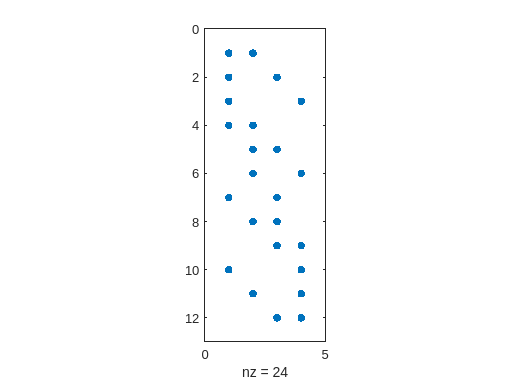


figure(1)
spy(A)
hold off

% check ranks of all of the different things
% kernel_rank = rank(kernel)
% kernel_rank_gap = base_dim - rank(kernel)
% 
% Qother_mid_rank = rank(Qother_middle)
% Qother_mid_rank_gap = base_dim - rank(Qother_middle)
% Qother_right_rank = rank(full(Qother_right))
% Qother_right_rank_gap = base_dim - rank(full(Qother_right))
% Qother_rank_gap = size(Qother, 1) - rank(full(Qother))
% 
% tij = M * X_gt_marg;
% tij - (A * -X_gt_trans)

nl_Qhand = null(Qhand);
nl_Qmid = null(Qother_middle);
corank_before_X_gt = size(nl_Qhand, 2)

corank_before_X_gt =      3


Rot1 = zeros(n, 2);
rotlen = npose/2*d;
rotidxs = 1:npose/2*d;
Rot1(rotidxs, :) = X_gt(rotidxs, :);
Qhand_plus = Qhand + Rot1 * Rot1';
Rot2 = zeros(n, 2);
Rot2(rotlen + rotidxs, :) = X_gt(rotlen + rotidxs, :);
Q3 = Qhand_plus + Rot2 * Rot2';
newest_null_after_X_gt = null(Qhand_plus);
nn = newest_null_after_X_gt;
corank_after_X_gt = size(nn, 2)

corank_after_X_gt =      3



nn2 = null(Q3, 'rational');
corank_after_two_rots = size(nn2, 2)

corank_after_two_rots =      3


V2 = M*nn2;
V2(13:end,:)


ans =

  0×3 empty double matrix




for i = 1:size(nl_Qhand, 2)
    v = nl_Qhand(:, i);
    null_check = norm(Qhand * v)
    % disp('Null )
end

null_check =      1.357334478343702e-12


null_check =      5.202126476032632e-13


null_check =      6.835551205031183e-13




V = pinv(full(M)) * A(:, 1:end);
rankV = rank(V)

rankV =      3


clf
figure(2)
nrow = 1;
ncol = 3'

ncol =      3


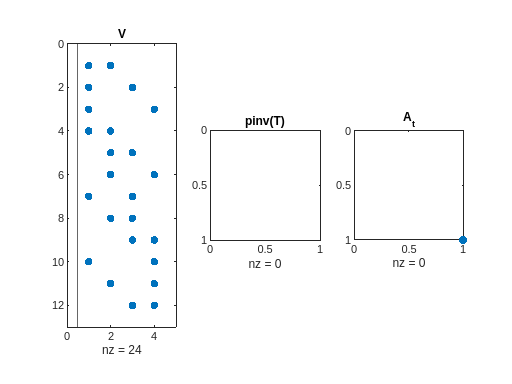

subplot(nrow, ncol, 1);
spy(V)
title("V");
xline(npose + 0.5)
yline(npose*d)
subplot(nrow, ncol, 2);
spy(pinv(full(T)))
title("pinv(T)");
subplot(nrow, ncol, 3);
spy(A_t)
title("A_t");
hold on


Vuse = V(:, npose+1:end);


for i = 1:size(V, 2)
    % a = V(:, randi(size(V, 2)));
    a = V(:, i);
    a = a / norm(a);
    
    null_test = norm((a));
    null_test = norm((M * a));
    null_test = norm((sqrtOmega * M * a));
    null_test = norm((speye(size(Omega)) * sqrtOmega * M * a));
    null_test = norm((kernel) * sqrtOmega * M * a);
    null_test = norm((speye(size(Omega)) - kernel) * sqrtOmega * M * a);
    
    null_test = norm(Qother * a);
    % null_test = norm(LrhoPad * a);
    % null_test = norm(Qhand * a);
    % null_test = norm(X_gt_marg * X_gt_marg' * a);
    disp("Null test: " + null_test)
    
    Qtest = norm((Qhand_plus  * a));
end

Null test: 2.6045e-13
Null test: 8.2717e-13
Null test: 3.242e-13
Null test: 1.704e-12


## 2 robots, 1 landmark, no loop closures

Robots: 2 || Variables: 10 poses, 1 landmarks || Measurements: 8 odom, 0 pose to landmark, 6 range, 0 loop closures, Interrobot loop closures: No inter-robot loop closures

fpath = "/home/alan/temp5.pyfg";
prob = parse_pyfg_text(fpath, use_marginalized_solver, verbose)

Using marginalized product.
Reading data from /home/alan/temp5.pyfg


Finished loading data in 0.006836 seconds.


prob = struct with fields:
                  use_marginalized: 1
                               dim: 2
                        num_robots: 2
                         num_poses: 10
         num_rel_pose_measurements: 12
    num_pose_landmark_measurements: 0
                     num_landmarks: 1
            num_range_measurements: 12
                        all_R_idxs: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20]
                        all_d_idxs: [21 22 23 24 25 26 27 28 29 30 31 32]
                        all_t_idxs: [33 34 35 36 37 38 39 40 41 42]
                        all_l_idxs: 43
                              X_gt: [43×2 double]
                            X_odom: [43×2 double]
                                 V: [11×20 double]
                              Lrho: [20×20 double]
                             Apose: [12×11 double]
                             Omega: [12×12 double]
                                 T: [12×20 double]
                            Arange: [12×1

n = size(prob.Qmain, 1);
npose = prob.num_poses;
d = prob.dim;
l = prob.num_range_measurements;
t = prob.num_landmarks+prob.num_poses;
trans_idxs = prob.all_t_idxs;
range_idxs = prob.all_d_idxs;
rot_idxs = prob.all_R_idxs;
X_gt = prob.X_gt;

X_gt_marg = X_gt(1:n, :);
X_gt_rot = X_gt(rot_idxs, :);
X_gt_range = X_gt(range_idxs, :);
X_gt_trans = X_gt(size(prob.Qmain, 1)+1:end, :);

Omega_t = prob.debug.Omega_t;
Omega_r = prob.debug.Omega_r;
A_t = prob.debug.A_t;
A_r = prob.debug.A_r;
T = prob.debug.T;
D = prob.debug.D;
Lrho = prob.debug.LGrho;

M = blkdiag(T, D);
Omega = blkdiag(Omega_t, Omega_r);
Omega = diag([1:length(Omega)]);
% Omega = speye(size(Omega));
sqrtOmega = sqrt(Omega);
A = [A_t; A_r];

Qother_left = M' * sqrtOmega;
kernel = (pinv(full(A(:, 1:end)' * sqrtOmega)) * (A(:, 1:end)' * sqrtOmega));
Qother_middle = speye(size(Omega)) - kernel; % rank = # measurements - # translation variables
Pi = Qother_middle;
Qother_right = Qother_left';
Qother = Qother_left * Qother_middle * Qother_right; 
    % rank = # measurements - # translation variables
    % size = dn + r
Qtemp =  Qother_middle * Qother_right;

AsqrtOmega = A' * sqrtOmega;
pad_dim = size(Qother, 1) - size(Lrho, 1); 
LrhoPad = blkdiag(Lrho, zeros(pad_dim));
Qhand = LrhoPad + Qother;

base_dim = size(Qhand, 1)

base_dim =     32


rank(Qhand)

ans =     26


nl = null(Qhand);
nl_Lrho = null(full(Lrho));
nl_Qother = null(Qother);
nl_A = null(full(A'), 'rational');
nl_kernel = null(kernel);
corank_Qhand = size(nl, 2)

corank_Qhand =      6


corank_Lrho = size(nl_Lrho, 2)

corank_Lrho =      4


corank_Qother = size(nl_Qother, 2)

corank_Qother =     18


corank_A = size(nl_A, 2)

corank_A =     14


corank_kernel = size(nl_kernel, 2)

corank_kernel =     14


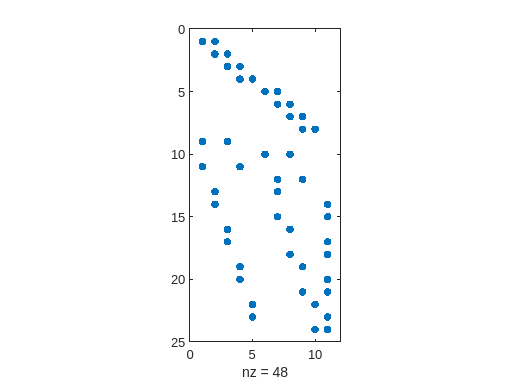


figure(1)
spy(A)
hold off

% check ranks of all of the different things
% kernel_rank = rank(kernel)
% kernel_rank_gap = base_dim - rank(kernel)
% 
% Qother_mid_rank = rank(Qother_middle)
% Qother_mid_rank_gap = base_dim - rank(Qother_middle)
% Qother_right_rank = rank(full(Qother_right))
% Qother_right_rank_gap = base_dim - rank(full(Qother_right))
% Qother_rank_gap = size(Qother, 1) - rank(full(Qother))
% 
% tij = M * X_gt_marg;
% tij - (A * -X_gt_trans)

nl_Qhand = null(Qhand);
nl_Qmid = null(Qother_middle);
corank_before_X_gt = size(nl_Qhand, 2)

corank_before_X_gt =      6


Rot1 = zeros(n, 2);
rotlen = npose/2*d;
rotidxs = 1:npose/2*d;
Rot1(rotidxs, :) = X_gt(rotidxs, :);
Qhand_plus = Qhand + Rot1 * Rot1';
Rot2 = zeros(n, 2);
Rot2(rotlen + rotidxs, :) = X_gt(rotlen + rotidxs, :);
Q3 = Qhand_plus + Rot2 * Rot2';
newest_null_after_X_gt = null(Qhand_plus);
nn = newest_null_after_X_gt;
corank_after_X_gt = size(nn, 2)

corank_after_X_gt =      4



nn2 = null(Q3, 'rational');
corank_after_two_rots = size(nn2, 2)

corank_after_two_rots =      2


V2 = M*nn2;
V2(13:end,:)

ans =    3.162277660000073 -15.297058541000091
   3.162277660000045   0.000000000000134
  -0.000000000000035  15.297058541000251
   3.162277660000073 -15.297058541000162
   3.162277660000036   0.000000000000145
  -0.000000000000045  15.297058541000306
   3.162277660000039 -15.297058541000039
   3.162277660000024   0.000000000000088
  -0.000000000000020  15.297058541000139
   3.162277660000002 -15.297058540999993



for i = 1:size(nl_Qhand, 2)
    v = nl_Qhand(:, i);
    null_check = norm(Qhand * v)
    % disp('Null )
end

null_check =      1.638782627764140e-11


null_check =      1.127085147708253e-11


null_check =      5.677279401626485e-12


null_check =      6.095590300602335e-12


null_check =      1.214121413344154e-11


null_check =      1.673144785499986e-11




V = pinv(full(M)) * A(:, 1:end);
rankV = rank(V)

rankV =     10


clf
figure(2)
nrow = 1;
ncol = 3'

ncol =      3


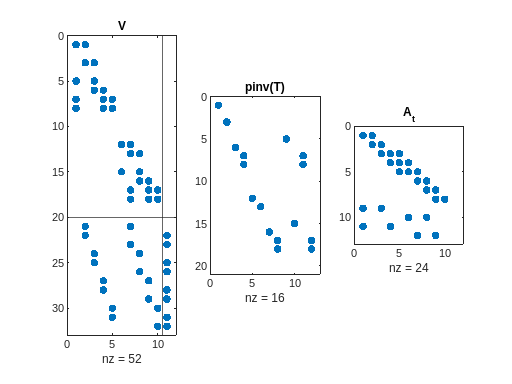

subplot(nrow, ncol, 1);
spy(V)
title("V");
xline(npose + 0.5)
yline(npose*d)
subplot(nrow, ncol, 2);
spy(pinv(full(T)))
title("pinv(T)");
subplot(nrow, ncol, 3);
spy(A_t)
title("A_t");
hold on


Vuse = V(:, npose+1:end);


for i = 1:size(V, 2)
    % a = V(:, randi(size(V, 2)));
    a = V(:, i);
    a = a / norm(a);
    
    null_test = norm((a));
    null_test = norm((M * a));
    null_test = norm((sqrtOmega * M * a));
    null_test = norm((speye(size(Omega)) * sqrtOmega * M * a));
    null_test = norm((kernel) * sqrtOmega * M * a);
    null_test = norm((speye(size(Omega)) - kernel) * sqrtOmega * M * a);
    
    null_test = norm(Qother * a);
    % null_test = norm(LrhoPad * a);
    % null_test = norm(Qhand * a);
    % null_test = norm(X_gt_marg * X_gt_marg' * a);
    disp("Null test: " + null_test)
    
    Qtest = norm((Qhand_plus  * a));
end

Null test: 7.1807e-14
Null test: 1.7441e-13
Null test: 1.9398e-13
Null test: 1.6967e-13
Null test: 3.2046e-13
Null test: 8.563e-14
Null test: 1.2441e-13
Null test: 1.8979e-13
Null test: 8.0056e-14
Null test: 3.1115e-13
Null test: 8.1851e-13


fpath = "/home/alan/two_timesteps_robot_only.pyfg";
prob = parse_pyfg_text(fpath, use_marginalized_solver, verbose);

Using marginalized product.
Reading data from /home/alan/two_timesteps_robot_only.pyfg


Finished loading data in 0.010537 seconds.


n = size(prob.Qmain, 1);
npose = prob.num_poses;
d = prob.dim;
l = prob.num_range_measurements;
t = prob.num_landmarks+prob.num_poses;
trans_idxs = prob.all_t_idxs;
range_idxs = prob.all_d_idxs;
rot_idxs = prob.all_R_idxs;
X_gt = prob.X_gt;

X_gt_marg = X_gt(1:n, :);
X_gt_rot = X_gt(rot_idxs, :);
X_gt_range = X_gt(range_idxs, :);
X_gt_trans = X_gt(size(prob.Qmain, 1)+1:end, :);

Omega_t = prob.debug.Omega_t;
Omega_r = prob.debug.Omega_r;
A_t = prob.debug.A_t;
A_r = prob.debug.A_r;
T = prob.debug.T;
D = prob.debug.D;
Lrho = prob.debug.LGrho;

M = blkdiag(T, D);
Omega = blkdiag(Omega_t, Omega_r);
Omega = diag([1:length(Omega)]);
% Omega = speye(size(Omega));
sqrtOmega = sqrt(Omega);
A = [A_t; A_r];

Qother_left = M' * sqrtOmega;
kernel = (pinv(full(A(:, 1:end)' * sqrtOmega)) * (A(:, 1:end)' * sqrtOmega));
Qother_middle = speye(size(Omega)) - kernel; % rank = # measurements - # translation variables
Pi = Qother_middle;
Qother_right = Qother_left';
Qother = Qother_left * Qother_middle * Qother_right; 
    % rank = # measurements - # translation variables
    % size = dn + r
Qtemp =  Qother_middle * Qother_right;

AsqrtOmega = A' * sqrtOmega;
LrhoPad = blkdiag(Lrho, zeros(size(Qother, 1) - size(Lrho, 1)));
Qhand = LrhoPad + Qother;

base_dim = size(Qhand, 1)

base_dim = 14

rank(Qhand)

ans = 9

nl = null(Qhand);
nl_Lrho = null(full(Lrho));
nl_Qother = null(Qother);
nl_A = null(full(A'), 'rational');
nl_kernel = null(kernel);
corank_Qhand = size(nl, 2)

corank_Qhand = 5

corank_Lrho = size(nl_Lrho, 2)

corank_Lrho = 4

corank_Qother = size(nl_Qother, 2)

corank_Qother = 13

corank_A = size(nl_A, 2)

corank_A = 1

corank_kernel = size(nl_kernel, 2)

corank_kernel = 1

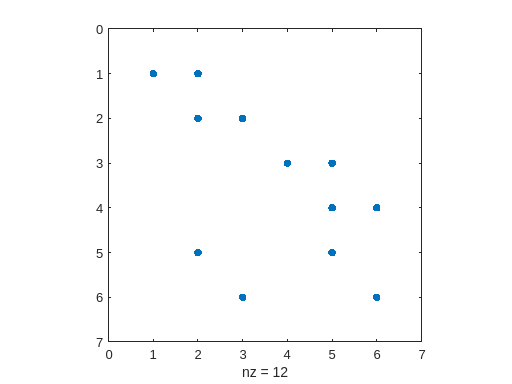


figure(1)
spy(A)
hold off

% check ranks of all of the different things
% kernel_rank = rank(kernel)
% kernel_rank_gap = base_dim - rank(kernel)
% 
% Qother_mid_rank = rank(Qother_middle)
% Qother_mid_rank_gap = base_dim - rank(Qother_middle)
% Qother_right_rank = rank(full(Qother_right))
% Qother_right_rank_gap = base_dim - rank(full(Qother_right))
% Qother_rank_gap = size(Qother, 1) - rank(full(Qother))
% 
% tij = M * X_gt_marg;
% tij - (A * -X_gt_trans)

nl_Qhand = null(Qhand);
nl_Qmid = null(Qother_middle);
corank_before_X_gt = size(nl_Qhand, 2)

corank_before_X_gt = 5

Rot1 = zeros(n, 2);
rotlen = npose/2*d;
rotidxs = 1:npose/2*d;
Rot1(rotidxs, :) = X_gt(rotidxs, :);
Qhand_plus = Qhand + Rot1 * Rot1';
Rot2 = zeros(n, 2);
Rot2(rotlen + rotidxs, :) = X_gt(rotlen + rotidxs, :);
Q3 = Qhand_plus + Rot2 * Rot2';
newest_null_after_X_gt = null(Qhand_plus);
nn = newest_null_after_X_gt;
corank_after_X_gt = size(nn, 2)

corank_after_X_gt = 3


nn2 = null(Q3, 'rational');
corank_after_two_rots = size(nn2, 2)

corank_after_two_rots = 1

V2 = M*nn2

V2 =     0.0000
   -0.0000
         0
         0
   18.4391
   18.4391



for i = 1:size(nl_Qhand, 2)
    v = nl_Qhand(:, i);
    null_check = norm(Qhand * v)
    % disp('Null )
end

null_check = 5.4360e-12

null_check = 5.9654e-12

null_check = 4.0062e-12

null_check = 3.8880e-12

null_check = 4.0877e-12



V = pinv(full(M)) * A(:, 1:end);
rankV = rank(V)

rankV = 5

clf
figure(2)
nrow = 1;
ncol = 3'

ncol = 3

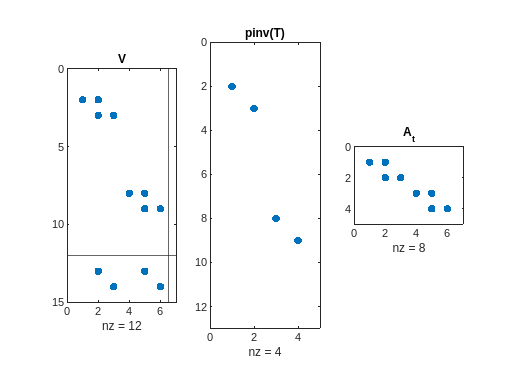

subplot(nrow, ncol, 1);
spy(V)
title("V");
xline(npose + 0.5)
yline(npose*d)
subplot(nrow, ncol, 2);
spy(pinv(full(T)))
title("pinv(T)");
subplot(nrow, ncol, 3);
spy(A_t)
title("A_t");
hold on


Vuse = V(:, npose+1:end);

for i = 1:size(V, 2)
    % a = V(:, randi(size(V, 2)));
    a = V(:, i);
    a = a / norm(a);
    
    null_test = norm((a));
    null_test = norm((M * a));
    null_test = norm((sqrtOmega * M * a));
    null_test = norm((speye(size(Omega)) * sqrtOmega * M * a));
    null_test = norm((kernel) * sqrtOmega * M * a);
    null_test = norm((speye(size(Omega)) - kernel) * sqrtOmega * M * a);
    
    null_test = norm(Qother * a);
    % null_test = norm(LrhoPad * a);
    % null_test = norm(Qhand * a);
    % null_test = norm(X_gt_marg * X_gt_marg' * a);
    disp("Null test: " + null_test)
    
    Qtest = norm((Qhand_plus  * a));
end

Null test: 1.4809e-15
Null test: 2.6798e-14
Null test: 4.6236e-14
Null test: 4.5359e-14
Null test: 6.7576e-14
Null test: 2.8504e-14


## SDP solve with SEDUMI

tic;
sdpdim = size(Qhand, 1);
X = sdpvar(sdpdim)

Linear matrix variable 14x14 (symmetric, real, 105 variables)
Coefficient range: 1 to 1



Objective = trace(Qhand * X)

Linear scalar (real, 39 variables)
Coefficients range: 7.494e-16 to 20000.8955



Constraints = [X >= 0];
for i = 1:npose
    Constraints = [Constraints, X(i*d-d+1:i*d, i*d-d+1:i*d) == eye(d)];
end
for i = npose+1:sdpdim
    Constraints = [Constraints, X(i, i) == 1];
end

% Solver options (e.g., using SDPT3 or SeDuMi)
options = sdpsettings('solver', 'sedumi'); % or 'sedumi'

% Solve the problem
sol = optimize(Constraints, Objective, options);

% Check the solution
if sol.problem == 0
    disp('Solver converged to a solution');
    X_opt = value(X);
    disp('Optimal solution X:');
    disp(X_opt);
else
    disp('Solver did not converge');
    disp(sol.info);
end

Solver did not converge


Numerical problems (<a href="yalmip.github.io/inside/debuggingnumerics">learn to debug</a>) (SeDuMi)


toc;

Elapsed time is 0.130859 seconds.


%%

[V, D] = eigs(X_gt_marg * X_gt_marg' + 1e-10*speye(size(Qhand)), 30);
Xnew = V * sqrt(D);
% K = prob.stacked_constraints;
K = [prob.stacked_constraints; Qhand];
trace(Qhand * X_opt)
cost = abs(trace(Qhand * Xnew * Xnew'));
rk = rank(Xnew);
svds = svd(Xnew);
% disp("cost: " + cost + " rank: " + rk + " svds: ")
% disp(svds)

Xgt = get_lower_rank_solution(X_gt_marg, [prob.stacked_constraints; Qhand]);


Xnew = get_lower_rank_solution(Xnew, prob.stacked_constraints);
cost = abs(trace(Qhand * Xnew * Xnew'));
rk = rank(Xnew);
svds = svd(Xnew);
disp("cost: " + cost + " rank: " + rk + " svds: ")
disp(svds)

Xnew = [Xnew, X_gt_marg];
Xnew = get_lower_rank_solution(Xnew, [prob.stacked_constraints; Qhand]);
cost = abs(trace(Qhand * (Xnew * Xnew')));
rk = rank(Xnew);
svds = svd(Xnew);
disp("cost: " + cost + " rank: " + rk + " svds: ")
disp(svds)
